Function

format longG

f=@(x) (1 - x - 4.*x.^3 + 2.*x.^5)

f = function_handle with value:
    @(x)(1-x-4.*x.^3+2.*x.^5)


xx = linspace(-2,4)

xx =                         -2         -1.93939393939394         -1.87878787878788         -1.81818181818182         -1.75757575757576          -1.6969696969697         -1.63636363636364         -1.57575757575758         -1.51515151515152         -1.45454545454545         -1.39393939393939         -1.33333333333333         -1.27272727272727         -1.21212121212121         -1.15151515151515         -1.09090909090909         -1.03030303030303         -0.96969696969697        -0.909090909090909        -0.848484848484848        -0.787878787878788        -0.727272727272727        -0.666666666666667        -0.606060606060606        -0.545454545454545        -0.484848484848485        -0.424242424242424        -0.363636363636364        -0.303030303030303        -0.242424242424242        -0.181818181818182        -0.121212121212121       -0.0606060606060606                         0        0.0606060606060606         0.121212121212121         0.181818181818182         0.242424242424242       

yy = f(xx)

yy =                        -29          -22.755617836775         -17.4125350165769         -12.8787092287536         -9.06818165847983         -5.90088074495636         -3.30242593960919          -1.2039314642886         0.458189930531681          1.74242320755537          2.70234728446447          3.38683127572016          3.84023073436365          4.10258389381704          4.20980790968421          4.19389510155168          4.08310919478948          3.90218156235201          3.67250746657891          3.41234230099593           3.1369978321158          2.85903844123911          2.58847736625514          2.33297294344278          2.09802484927135           1.8871703422015          1.70218050448605          1.54325648397092          1.40922573589589          1.29773826469559          1.20546286580027          1.12828336743673          1.06149487242916                         1         0.938505127570841         0.871716632563266         0.794537134199726         0.702261735304409       

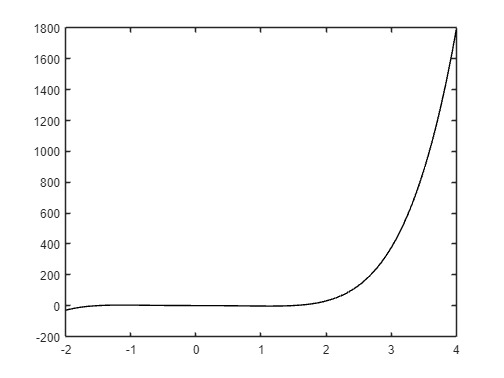

plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = -2

a =     -2


b = 4

b =      4


p =[2 0 -4 0 -1 1]

p =      2     0    -4     0    -1     1


q = polyint(p)

q =          0.333333333333333                         0                        -1                         0                      -0.5                         1                         0


Itrue = diff(polyval(q,[a,b]))

Itrue =         1104


Plot original function along with simpson 1/3 rule with ns = 1

ns = 4

ns =      4


x = linspace(a,b,2*ns+1)

x =                         -2                     -1.25                      -0.5                      0.25                         1                      1.75                       2.5                      3.25                         4


y = f(x)

y =                        -29               3.958984375                    1.9375               0.689453125                        -2              10.638671875                  131.3125             585.619140625                      1789



p2 = polyfit(x,y,2)

p2 =           100.410714285714          5.52700892857128         -205.571651785714


yy2 = polyval(p2,xx)

yy2 =           185.017187500001          161.378984446741          138.478417494753          116.315486644038          94.8901918945958          74.2025332464258          54.2525106995282          35.0401242539031          16.5653739095505         -1.17174033352973         -18.1712184753374         -34.4330605158727         -49.9572664551354         -64.7438362931257         -78.7927700298436          -92.104067665289         -104.677729199462         -116.513754632362          -127.61214396399         -137.972897194346         -147.596014323429          -156.48149535124         -164.629340277778         -172.039549103043         -178.712121827036         -184.647058449757         -189.844358971205         -194.304023391381         -198.026051710285         -201.010443927915         -203.257200044274          -204.76632005936         -205.537803973173         -205.571651785714         -204.867863496983         -203.426439106979         -201.247378615703         -198.330682023154      

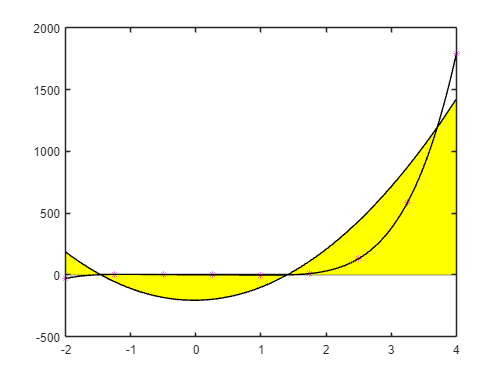

figure
area(xx,yy2,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
plot(xx,yy,'k-')

h = (b-a)/2;
Iap1 = sim13(f,a,b,4*2)%don't forget *2

Iap1 =                 1106.53125


%Iap1 = (3*h/8)*(f(a)+3*f((2*a+b)/3)+3*f((a+2*b)/3)+f(b))
err = abs(Itrue - Iap1)/Itrue

err =        0.00229279891304348


err = err*100

err =          0.229279891304348


Plot original function along with simpson 1/3 rule with ns = 2

ns = 2

ns =      2


x = linspace(a,b,2*ns+1)

x =                         -2                      -0.5                         1                       2.5                         4


y = f(x)

y =                        -29                    1.9375                        -2                  131.3125                      1789



figure
color = ['g','y']

color = 'gy'

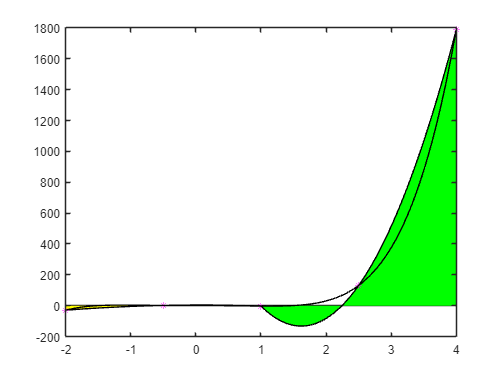

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule with ns = 3

ns = 3

ns =      3


x = linspace(a,b,2*ns+1)

x =     -2    -1     0     1     2     3     4


y = f(x)

y =          -29           4           1          -2          31         376        1789



figure
color = ['g','y']

color = 'gy'

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule from ns = 1 to 10

xx = linspace(-2,4,6)

xx =                         -2                      -0.8                       0.4                       1.6                       2.8                         4


yy = f(xx)

yy =                        -29                   3.19264                   0.36448                   3.98752                 254.59936                      1789


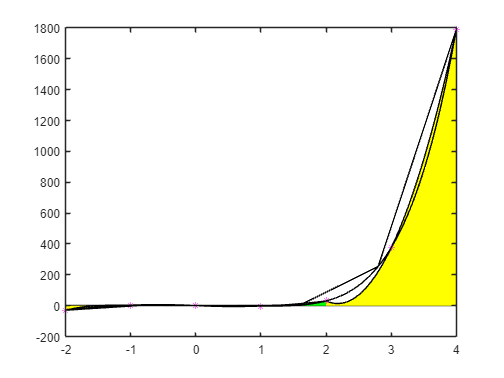

plot(xx,yy,'k-')

a = -2

a =     -2


b = 0.4

b =                        0.4


h = (b-a)/2;
Iap1 = sim13(f,a,b,1*2)%don't forget *2

Iap1 =                  -6.345984



a = 0.4

a =                        0.4


b = 4

b =      4


h = (b-a)/3;
Iap2 = (3*h/8)*(f(a)+3*f((2*a+b)/3)+3*f((a+2*b)/3)+f(b))

Iap2 =                1154.306304


sumap = Iap1+Iap2

sumap =                 1147.96032


err = abs(Itrue - sumap)/Itrue

err =         0.0398191304347827


err = err*100

err =           3.98191304347827
